# Filter Analysis

#### by Rodolfo Muñoz

## 1) Analysis of **LTI systems**

 Given the following LTI System:


$$y[n] = 0.81y[n-2] + x[n] - x[n-2]$$


It's transfer function **H(z)** can be obtained using the **Z Transform**: 


$$Y(z) = 0.81Y(z)z^{-2} + X(z) - X(z)z^{-2}$$



$$Y(z) (1-0.81z^{-2}) = X(z) (1-z^{-2}) $$



$$Y(z) = \frac{1-z^{-2}}{1-0.81z^{-2}} X(z)$$



$$H(z) = \frac{1-z^{-2}}{1-0.81z^{-2}}$$


Then, the transfer function can be represented by its **poles** and **zeros** with:

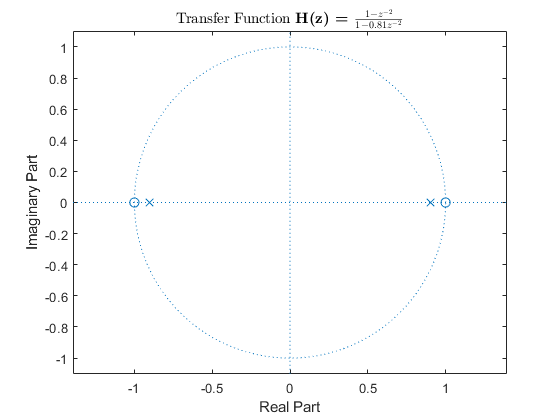

clc; clear variables; close all;
b = [1 0 -1];       % zeros
a = [1 0 -0.81];    % poles
figure('Name','Z Plane');
Hz = zplane(b,a);
title('Transfer Function \bf{H(z)} = $\frac{1-z^{-2}}{1-0.81z^{-2}}$',"Interpreter","latex");

To analyze the **response** to an **impulse** and an **step** signal we can use:

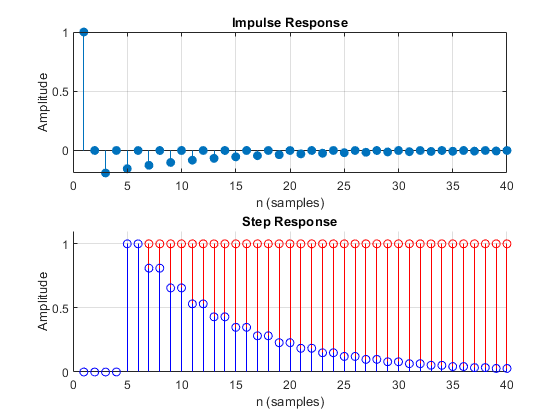

N = 40;
h = impz(b,a,N);
x = [zeros(1,floor(N/10)) ones(1,floor(9*N/10))];
y = filter(b,a,x);

figure('Name','Filter Responses')
subplot(2,1,1); 
stem(h,'filled'); grid on;
title('Impulse Response')
ylabel("Amplitude")
xlabel("n (samples)")

subplot(2,1,2); hold on; 
stem(x,'r'); 
stem(y,'b'); 
hold off; grid on;
axis([0 N 0 1.1*max(y)])
title('Step Response')
ylabel("Amplitude")
xlabel("n (samples)")

Finally, we analyze the **magnitude** and **phase** of the transfer function **H(z)**

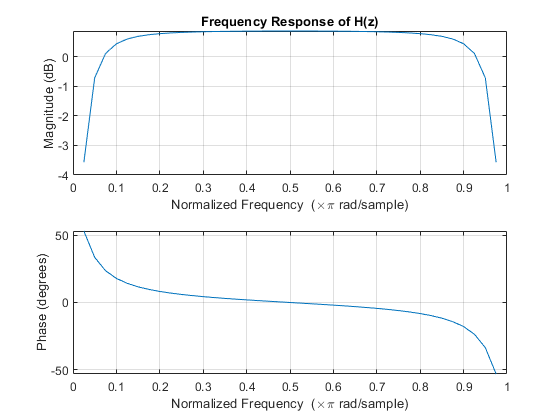

figure('name','Frequency Response')
freqz(b,a,N)
title('Frequency Response of H(z)')

## 2) Filter classification (Low Pass, High Pass, Passband)

- 
$$y[n]+0.13y[n-1]+0.52y[n-2]+0.3y[n-3] = 0.16x[n] - 0.48x[n-1] + 0.48x[n-2] - 0.16x[n-3]$$


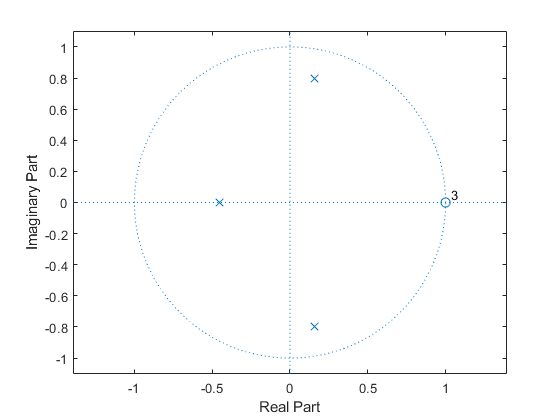

clear variables; close all;
N = 50;
b = [0.16 -0.48 0.48 -0.16];
a = [1 0.13 0.52 0.3];
figure('Name','Z Plane')
zplane(b,a);

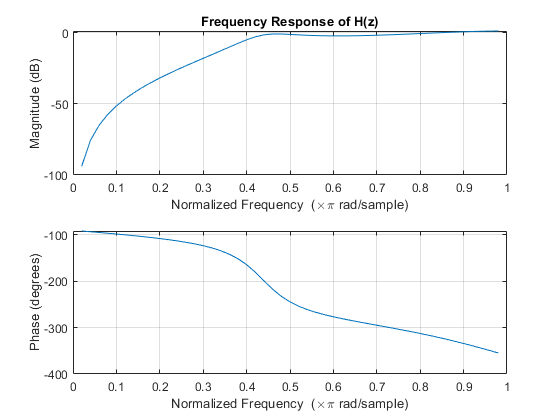

figure('Name','Frequency Response')
freqz(b,a,N);
title('Frequency Response of H(z)')

Here we have a **3rd order High Pass Filter**, with a nonlinear phase that has a mayor inflection point at... 

p = roots(a);
sympref('FloatingPointOutput',true);
syms omega_1 n;
omega_1/n == angle(p(1))/pi

$$ans = \frac{\omega_{1}}{n}=0.4369$$

w_n1 = angle(p(1))/pi;

Which also represents the start of the passband ass seen in this plot:

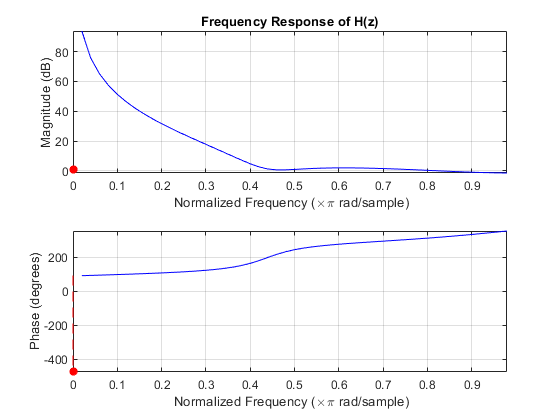

z_1 = filteranalyzer(a, b, N, true);

- 
$$y[n]-0.268y[n-2] = 0.634x[n] - 0.634x[n-2]$$


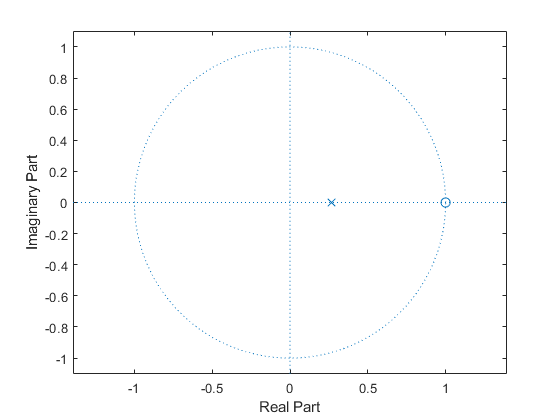

b = [0.634 -0.634];
a = [1 -0.268];
figure('Name','Z Plane')
zplane(b,a);

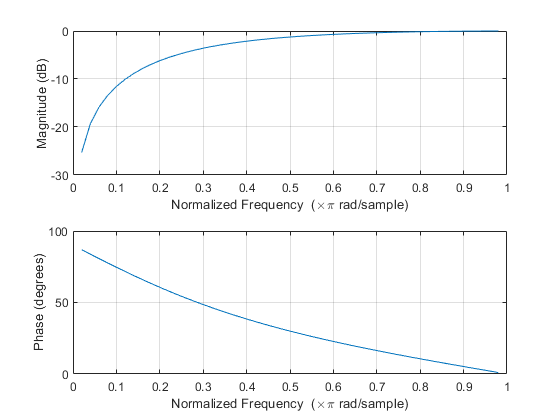

figure('Name','Frequency Response')
freqz(b,a,N)

**1st order High Pass Filter**, nonlinear phase

- 
$$y[n]+0.268y[n-2] = 0.634x[n] + 0.634x[n-2]$$


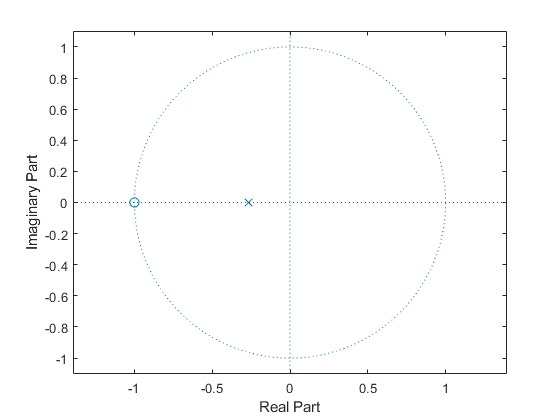

b = [0.634 0.634];
a = [1 0.268];
figure('Name','Z Plane')
zplane(b,a);

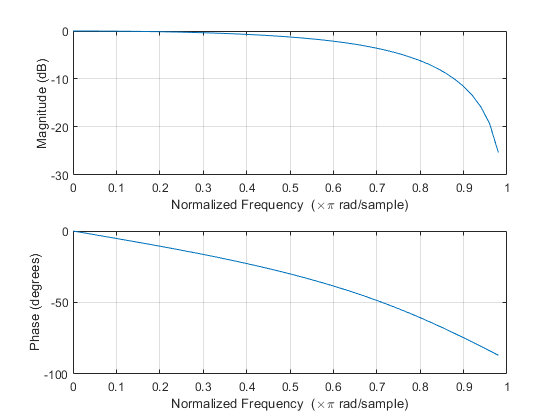

figure('Name','Frequency Response')
freqz(b,a,N)

**1st order Low Pass Filter**, nonlinear phase

- 
$$10y[n] - 5y[n-1] + y[n-2] = x[n] - 5x[n-1] + 10x[n-2]$$


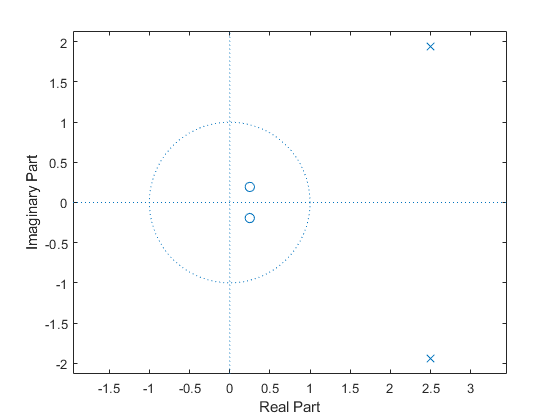

b = [10 -5 1];
a = [1 -5 10];
figure('Name','Z Plane')
zplane(b,a);

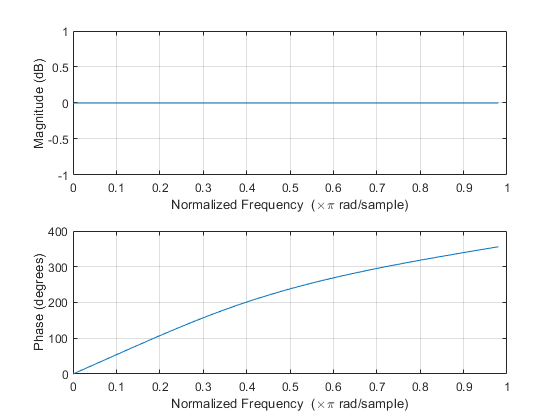

figure('Name','Frequency Response')
freqz(b,a,N)

While the frequency response suggest a Pass Band Filter, the **system is unstable as the poles are outside the unit circle**, therefore it cannot be used a filter.

## 3) Distortion classification (magnitude, phase, both)

 Let $x$ be the following signal defined in the interval $0\leq n \leq 60
$:


$$x[n] = sin(0.1\pi n) + \frac{1}{3}sin(0.3\pi n) + \frac{1}{5}sin(0.5\pi n)$$


clc; clear variables; %close all;
n = 0:60;
x = sin(0.1*pi*n) + 1/3*sin(0.3*pi*n) + 1/5*sin(0.5*pi*n);

Now, we'll analyze what type of distortion do the following systems have in the input signal:

- 
$$h[n] = \{\underline{1}, -2, 3, -4, 0, 4, -3, 2, -1\}$$


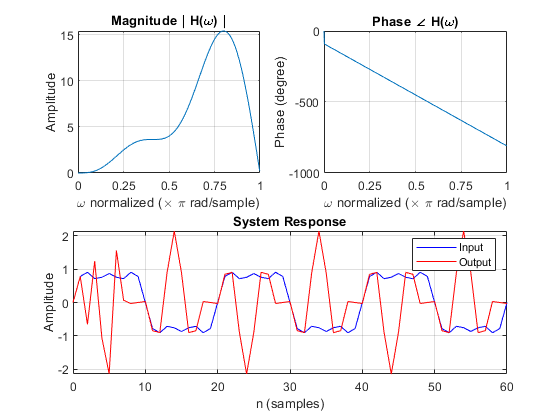

h = [1, -2, 3, -4, 0, 4, -3, 2, -1];
filterresponse(h, 1, x);

**Magnitude distortion**. The $\mid FFT\mid$ it is not constant over frequencies. In the output signal, it is seen when the low frequency component $\left(0\ldotp 1\pi \;\right)$ almost dissapears while the highest frecuency one$\left(0\ldotp 5\pi \;\right)$is amplified greatly.

- 
$$y[n] = 10x[n-10]$$


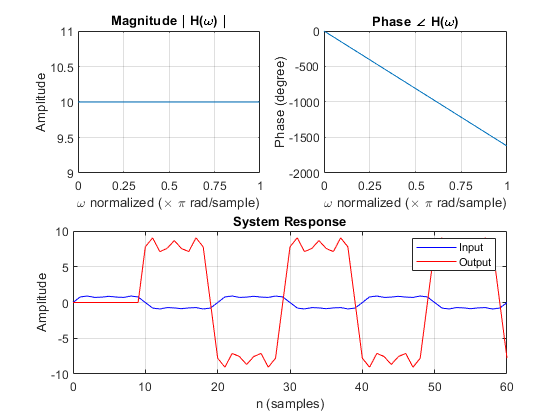

h = [zeros(1,9) 10];
filterresponse(h, 1, x);

**No distortion**, only a delay and amplification of the signal's strength. 

- 
$$H(z) = \frac{1}{9} (1+2z^{-1}+3z^{-2}+2z^{-3}+z^{-4})$$


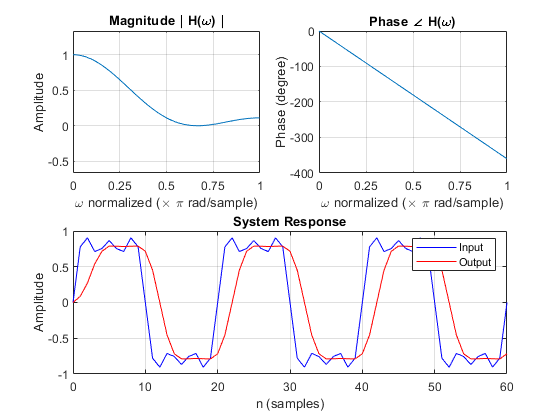

h = 1/9*[1 2 3 2 1];
filterresponse(h, 1, x);

**Magnitude distortion**. The systems has the nature of a Low Pass Filter, which can be seen by how smooth is the output signal in comparison to the input. 

- 
$$h[n] = \{\underline{1}, -1.1756,1\}$$


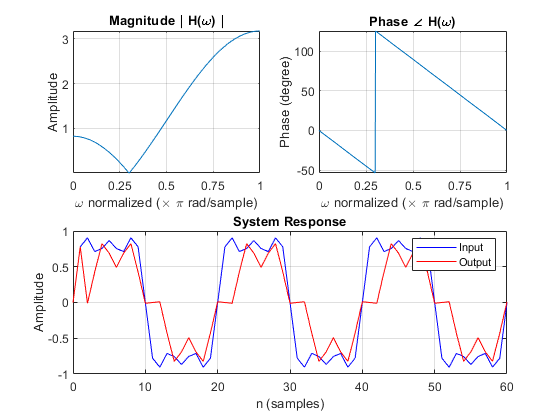

h = [1 -1.1756 1];
filterresponse(h, 1, x);

**Magnitude and phase distortion**. In this case the system has a zero exactly at the frequency of the middle signal $w_n =0\ldotp 3$ and also the phase sign shifts at that point, so the input is delayed differently depending on frequency. These effects can be seen in the shape change of the input after going through the filter. 

- 
$$H(z) = \frac{1 + 1.778z^{-2} +3.160z^{-4}}{1+0.5625z^{-2}+0.3164z^{-4} }$$


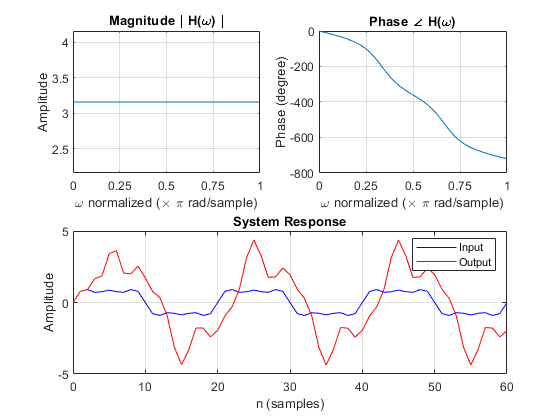

b = [1 0 1.778 0 3.16];
a = [1 0 0.5625 0 0.3164];
filterresponse(b, a, x);

**Phase distortion**. While the system has a constant magnitude response, it has a nonlinear phase which distorts the original waveform of the input signal completely.

## 4) Effect of sample size on filter response

We'll look at the Moving Average filter:


$$h[n]=$$
 
$$ \[ \begin{cases} 
      \frac{1}{M} & 0\leq  n\leq M-1 \\
       0               & otherwise 
   \end{cases}
\]$$


For that we'll use a loop that goes through different of values of M and see how its frequency response changes

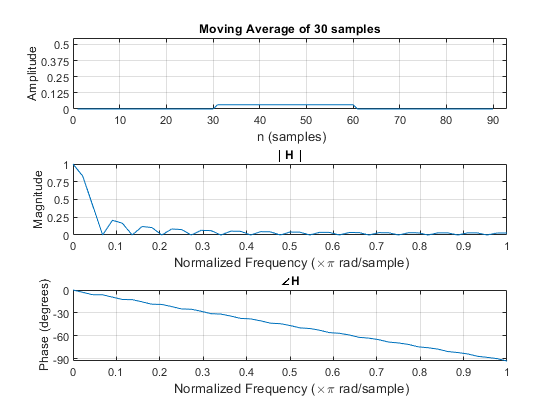

clear variables, close all;
M_max = 30; w_ticks = 0:pi/4:pi;  
figure('Name','Moving Average')
for M = 2:M_max
    h = [zeros(1,M) ones(1,M)/M zeros(1,M)];
    H = fft(h);
    L = floor(length(h)/2);    
    w = (0:L-1)/(L-1)*1;
    
    subplot(3,1,1)
    plot(h)
    axis([0 3*(M_max+1) 0 0.55])
    yticks([0:0.5/4:0.5])
    xlabel('\fontsize{10} n (samples)','Interpreter',"tex")
    ylabel('Amplitude')
    title(['Moving Average of ' num2str(M) ' samples'])
    grid on;
    
    subplot(3,1,2)
    plot(w,abs(H(1:L)))
    yticks([0:1/4:1])
    xlabel('\fontsize{10} Normalized Frequency (\times\pi rad/sample)','Interpreter',"tex")
    ylabel('Magnitude')
    title('\mid H \mid')
    axis tight, grid on;
    
    subplot(3,1,3)
    plot(w,unwrap(angle(H(1:L))))
    yticks([-90:30:0])
    ylabel('Phase (degrees)')
    xlabel('\fontsize{10} Normalized Frequency (\times\pi rad/sample)','Interpreter',"tex")
    title('\angleH')
    axis tight, grid on;
    
    pause(0.01)
end

As the filter becomes **bigger**, so does its **resolution** in the **frequency domain** and with that it resembles better the theoretical $sinc(\omega)$ response of the continuous filter. Also the bigger span of the average gives it a **stronger smoothing effect**, i.e. it is a Low Pass Filter with a cutoff frequncy that becomes smaller as M rises.